# Generate Signals in MATLAB

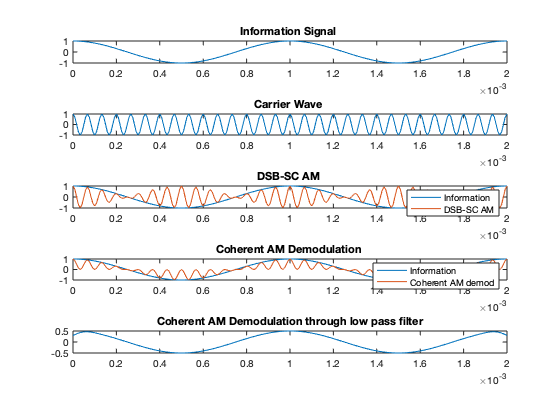

Ai = 1; % information amplitude
fi = 1000; % information frequency
Ac = 1; % carrier amplitude
fc = 15000; % information frequency
fs = 120000; % sampling frequency

% generate time vector
t = [0 : 1/ fs: 0.002 ]; % [ start : step : end ]
% generate sine wave
si = Ai*cos(2*pi*fi*t);
sc = Ac*cos(2*pi*fc*t);
sa = (Ai*Ac/2)*(cos(2*pi*(fc-fi)*t)+cos(2*pi*(fc+fi)*t));
sco = (Ai*Ac^2/2)*(cos(2*pi*fi*t) + cos(2*pi*(fc-fi)*t)/2 + cos(2*pi*(fc+fi)*t)/2);
% plot signal
subplot(5,1,1);
plot (t, si);
title ([ 'Information Signal ']);
subplot(5,1,2);
plot (t, sc);
title ([ 'Carrier Wave ']);
subplot(5,1,3);
plot (t, si);
hold on
plot (t, sa);
title ([ 'DSB-SC AM ']);
legend('Information','DSB-SC AM');
subplot(5,1,4);
plot (t, si);
hold on
plot (t, sco);
title ([ 'Coherent AM Demodulation ']);
legend('Information','Coherent AM demod');

%lpf
scol = lowpass(sco,fi,fs);
subplot(5,1,5);
plot (t, scol);
title ([ 'Coherent AM Demodulation through low pass filter']);